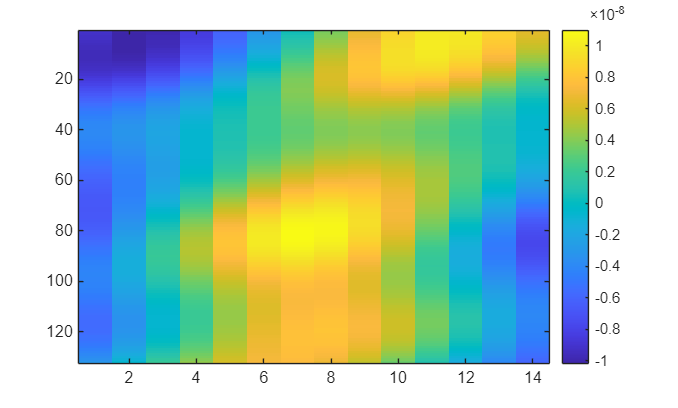

H_Aperfect = H_A300_perfect(:,:,2).';
H_Aperfect_real = real(H_Aperfect);
imagesc(H_Aperfect_real); colorbar()

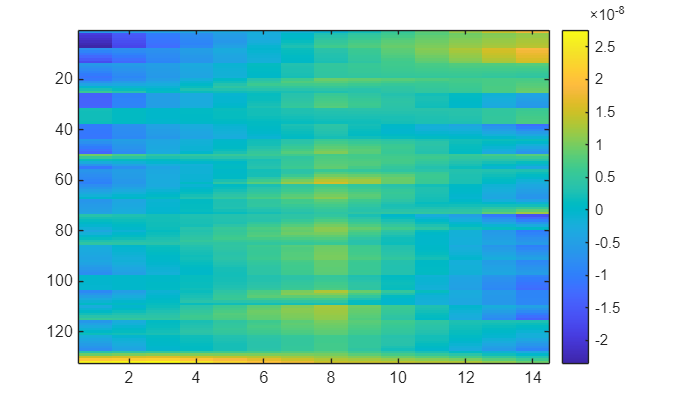

H_A = H_A300_li(:,:,2).';
H_A_real = real(H_A);
imagesc(H_A_real); colorbar()

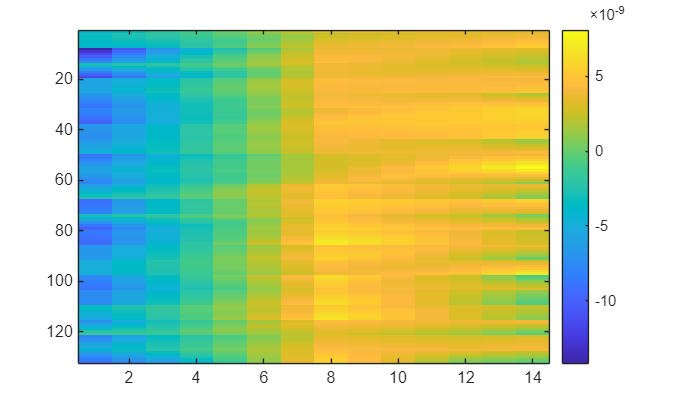

H_B = H_B100_300_li(:,:,1).';
H_B_real = real(H_B);
imagesc(H_B_real); colorbar()

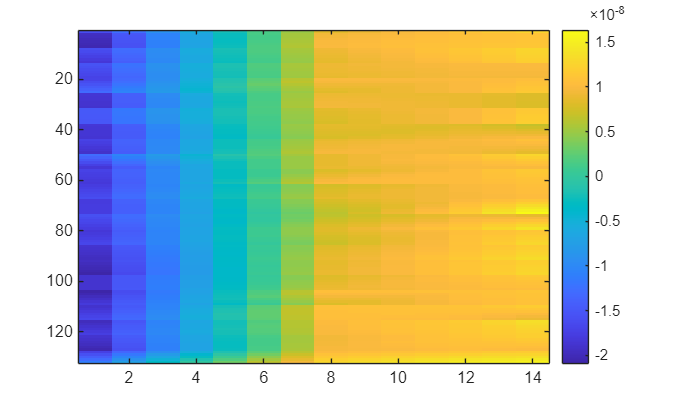

H_D = H_D30_li(:,:,1).';
H_D_real = real(H_D);
imagesc(H_D_real); colorbar()

function [amplitude_spectrum, phase_spectrum] = F_extract_DD(channel_grid)
% F_EXTRACT Converts Time-Freq channel to Delay-Doppler domain
% Input: 
%   channel_grid: 132 (Subcarriers) x 14 (Symbols) Complex Matrix
% Output:
%   amplitude_spectrum: Magnitude in Delay-Doppler (The "Style")
%   phase_spectrum: Phase in Delay-Doppler (The "Content")

    % 1. Transform Subcarriers (Frequency) -> Delay
    % We use IFFT along dimension 1 (Rows).
    % No shift needed here because delay is naturally 0 to Max.
    grid_delay = ifft(channel_grid, [], 1);
    
    % 2. Transform Symbols (Time) -> Doppler
    % We use FFT along dimension 2 (Columns).
    grid_delay_doppler_raw = fft(grid_delay, [], 2);
    
    % 3. Shift BOTH dimensions to Center
    % This moves (Delay=0, Doppler=0) to the middle of the matrix.
    grid_dd_shifted = fftshift(grid_delay_doppler_raw);
    
    % 4. Extract Amplitude and Phase
    amplitude_spectrum = abs(grid_dd_shifted);
    phase_spectrum = angle(grid_dd_shifted);

end

[A_amplitude_spectrum, A_phase_spectrum] = F_extract_DD(H_A);
[B_amplitude_spectrum, B_phase_spectrum] = F_extract_DD(H_B);
[D_amplitude_spectrum, D_phase_spectrum] = F_extract_DD(H_D);

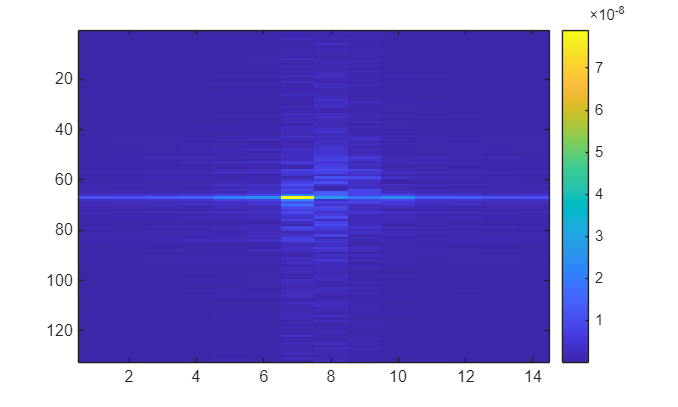

[n_subcarriers, n_symbols] = size(H_A);
doppler_axis = (-n_symbols/2 : n_symbols/2 - 1);
delay_axis = (-n_subcarriers/2 : n_subcarriers/2 - 1);
imagesc(A_amplitude_spectrum); colorbar

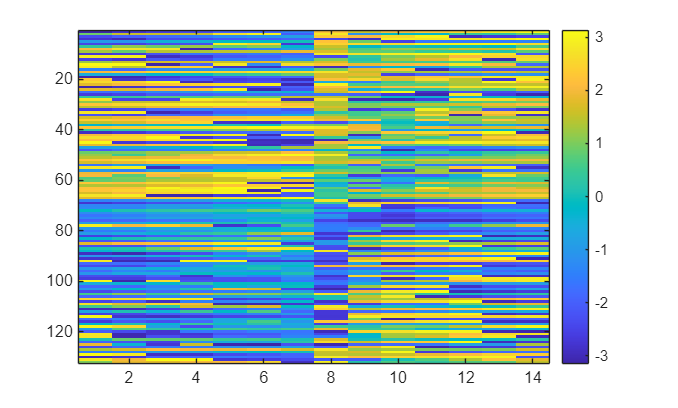

imagesc(A_phase_spectrum); colorbar

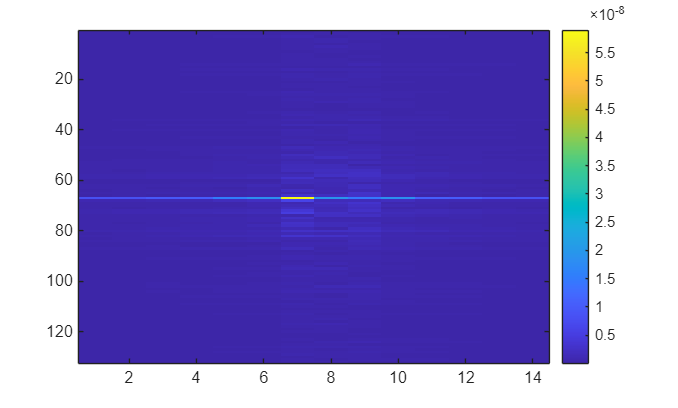

imagesc(B_amplitude_spectrum); colorbar

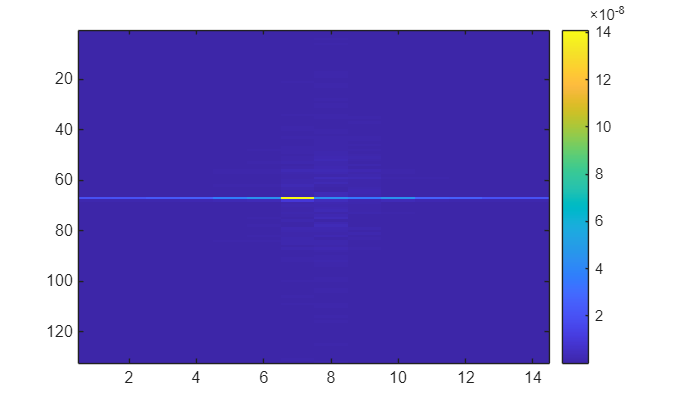

imagesc(D_amplitude_spectrum); colorbar

function [mixed_img] = fda_mix_pixels(source_img, target_img, win_h_px, win_w_px)
    % center: target
    % outer: source
    % 3. Calculate Center Coordinates
    [h, w] = size(source_img);
    cy = floor(h / 2) + 1;
    cx = floor(w / 2) + 1;   

    % 4. Determine Window Radius (Half-size)
    % We use floor to ensure we stay within integer indices
    % If you input 3 pixels, radius is 1 (Center +/- 1)
    r_h = floor(win_h_px / 2);
    r_w = floor(win_w_px / 2);

    % 5. Create the Mask
    % Initialize mask of zeros (use Source amplitude by default)
    mask = zeros(h, w);
    
    % Set the center region to 1 (use Target amplitude here)
    % We define the range explicitly around the center
    y_range = (cy - r_h) : (cy + r_h);
    x_range = (cx - r_w) : (cx + r_w);
    
    mask(y_range, x_range) = 1;
    
    % 6. Mix the Amplitudes
    % Logic: If mask is 1, take Target. If mask is 0, take Source.
    mixed_img = (mask .* target_img) + ((1 - mask) .* source_img); 
end

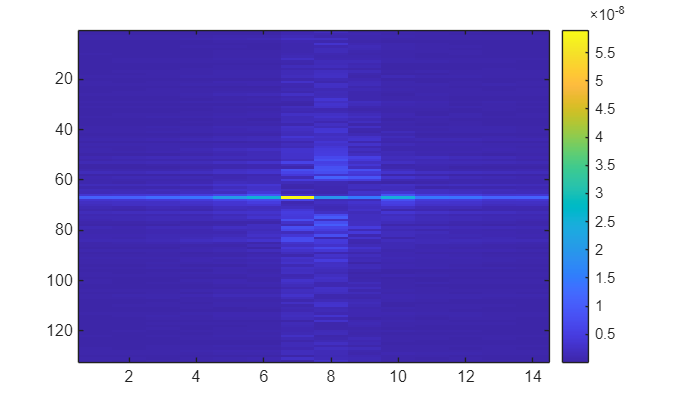

mix_AB = fda_mix_pixels(A_amplitude_spectrum, B_amplitude_spectrum, 13, 3);
    % center: B
    % outer: A
imagesc(real(mix_AB)); colorbar

fft_mixed = mix_AB .* exp(1i * A_phase_spectrum);

function [tf_grid] = F_inverse_DD(complex_dd)
% F_INVERSE_DD Converts Delay-Doppler grid back to Time-Freq grid
    % 1. Unshift Both Dimensions
    % Moves the Zero-Delay/Zero-Doppler peak from Center back to (1,1)
    grid_unshifted = ifftshift(complex_dd);
    
    % 2. Inverse Doppler -> Time (Dimension 2: Columns)
    % The Forward was FFT, so the Inverse is IFFT
    grid_delay_time = ifft(grid_unshifted, [], 2);
    
    % 3. Inverse Delay -> Frequency (Dimension 1: Rows)
    % The Forward was IFFT, so the Inverse is FFT
    tf_grid = fft(grid_delay_time, [], 1);
    
end

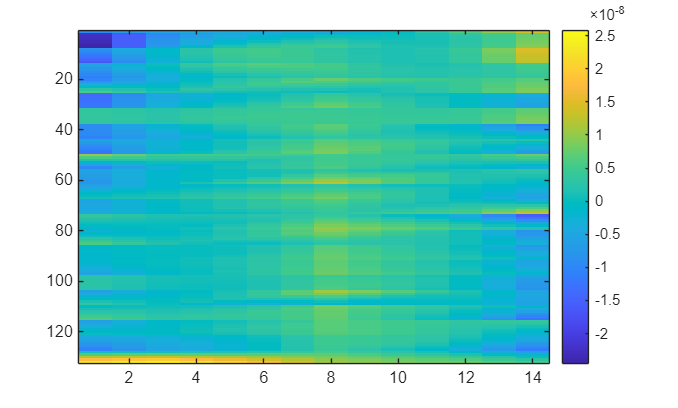

adapted_image = F_inverse_DD(fft_mixed);
    % center: B
    % outer: A
    % phase: A
imagesc(real(adapted_image)); colorbar

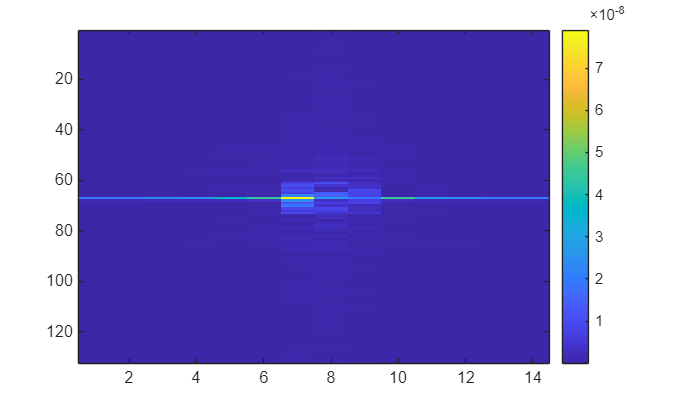

mix_DA = fda_mix_pixels(D_amplitude_spectrum, A_amplitude_spectrum, 13, 3);
    % center: A
    % outer: D
imagesc(real(mix_DA)); colorbar

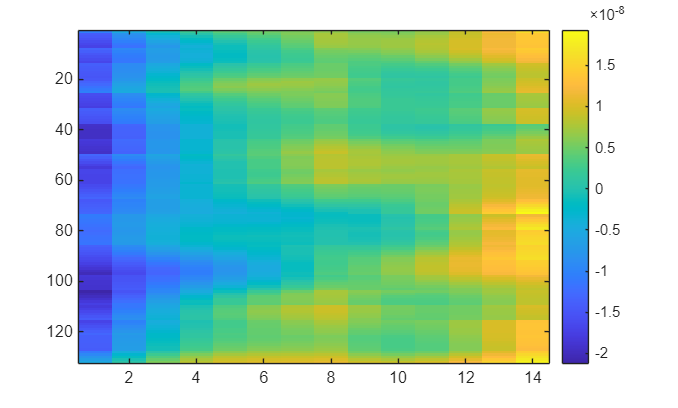

fft_mixedDA = mix_DA .* exp(1i * D_phase_spectrum);
adapted_imageDA = F_inverse_DD(fft_mixedDA);
    % center: A
    % outer: D
    % phase: D
imagesc(real(adapted_imageDA)); colorbar

## Translate ground truth D30 (label) to A300_li (input)

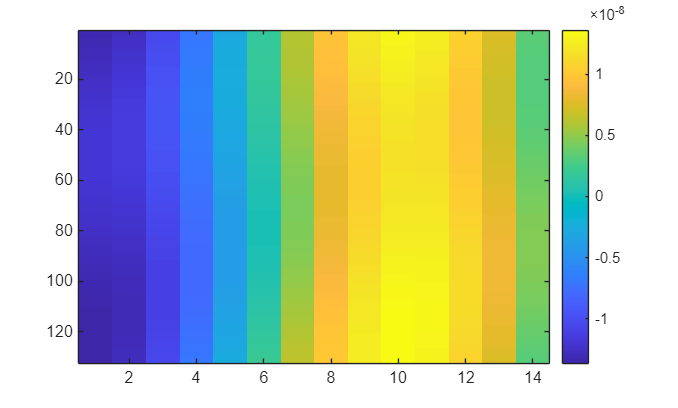

H_Dperfect = H_D30_perfect(:,:,1).';
H_Dperfect_real = real(H_Dperfect);
imagesc(H_Dperfect_real); colorbar()

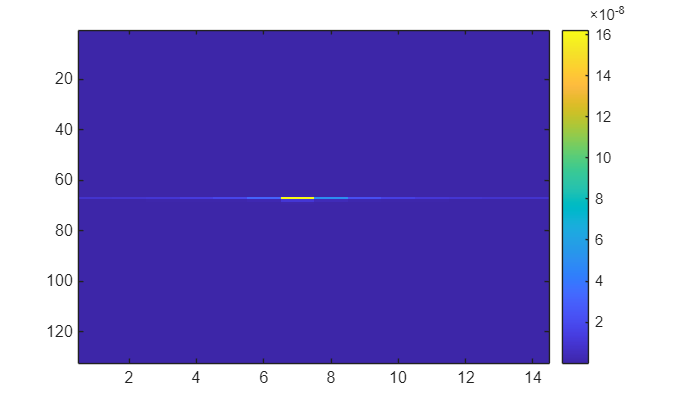

[Dperfect_amplitude_spectrum, Dperfect_phase_spectrum] = F_extract_DD(H_Dperfect);

imagesc(Dperfect_amplitude_spectrum); colorbar

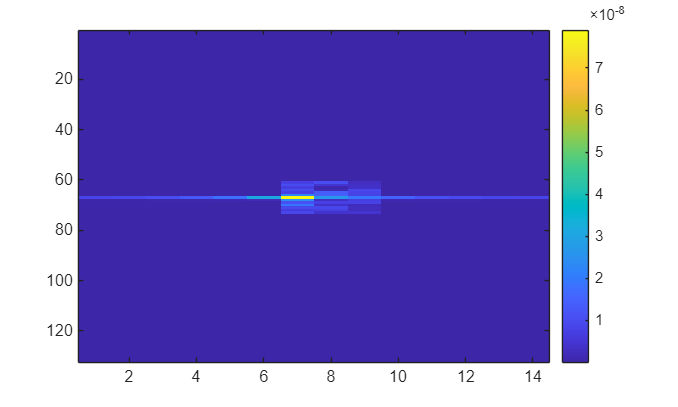

mix_DpA = fda_mix_pixels(Dperfect_amplitude_spectrum, A_amplitude_spectrum, 13, 3);
    % center: A li
    % outer: D perfect
imagesc(real(mix_DpA)); colorbar

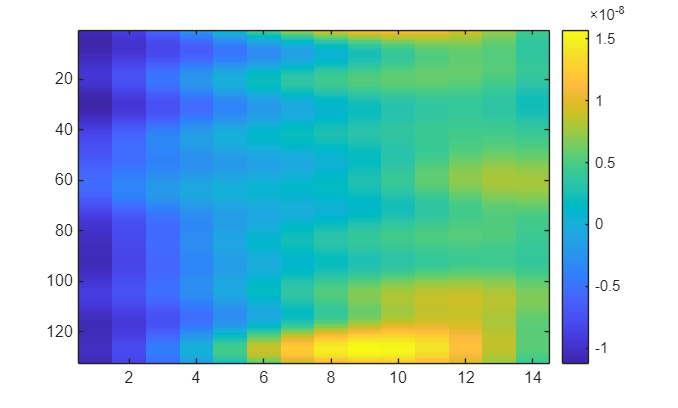

fft_mixedDpA = mix_DpA .* exp(1i * Dperfect_phase_spectrum);
adapted_imageDpA = F_inverse_DD(fft_mixedDpA);
    % center: A li
    % outer: D perfect
    % phase: D perfect
imagesc(real(adapted_imageDpA)); colorbar

## Translate A300_li to D30_perfect

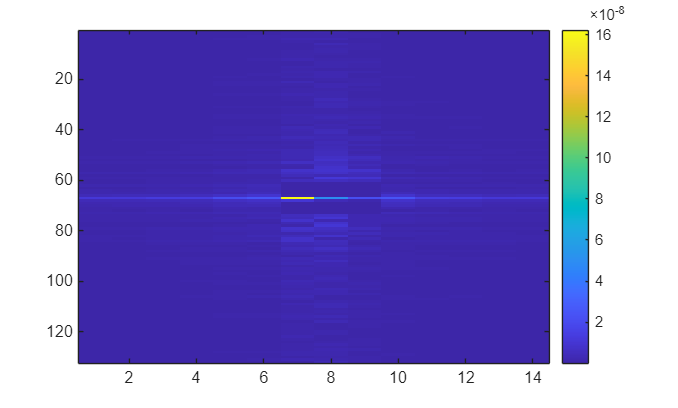

mix_ADp = fda_mix_pixels(A_amplitude_spectrum, Dperfect_amplitude_spectrum, 13, 3);
    % center: D perfect
    % outer: A li
imagesc(real(mix_ADp)); colorbar

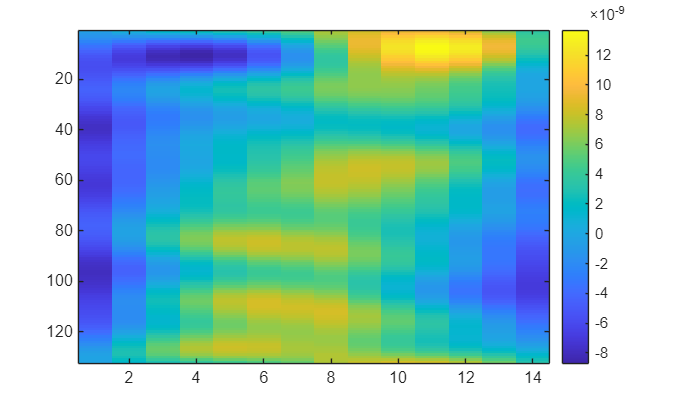

fft_mixedADp = mix_DpA .* exp(1i * A_phase_spectrum);
adapted_imageADp = F_inverse_DD(fft_mixedADp);
    % center: D perfect
    % outer: A li
    % phase: A li
imagesc(real(adapted_imageADp)); colorbar

## A300_li to D30_li

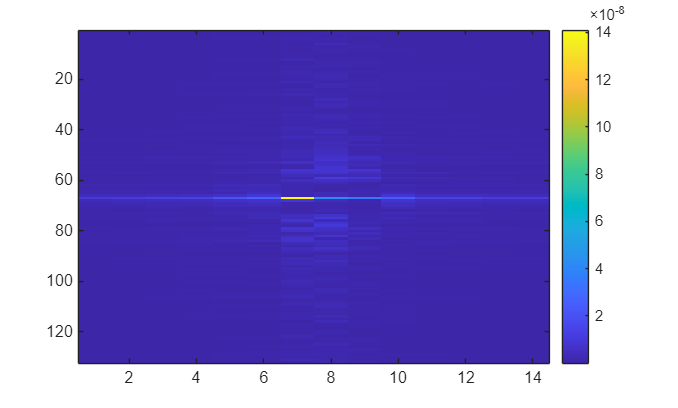

mix_AD = fda_mix_pixels(A_amplitude_spectrum, D_amplitude_spectrum, 13, 3);
    % center: D
    % outer: A
imagesc(real(mix_AD)); colorbar

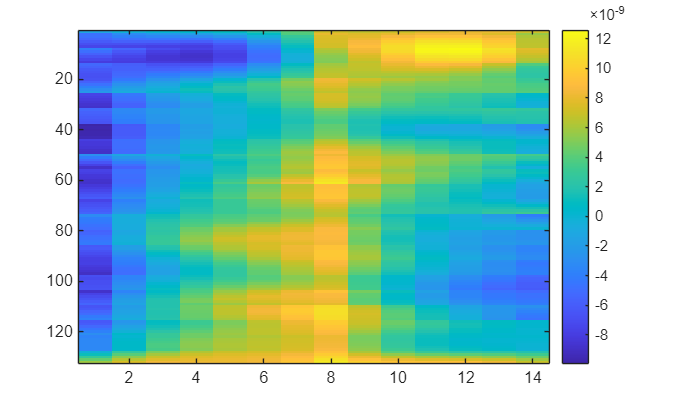

fft_mixedAD = mix_DA .* exp(1i * A_phase_spectrum);
adapted_imageAD = F_inverse_DD(fft_mixedAD);
    % center: D li
    % outer: A li
    % phase: A li
imagesc(real(adapted_imageAD)); colorbar